# **AERO 302 Fluids Assignment #2**

clc
clear 
close all

## ISF2 Plots:

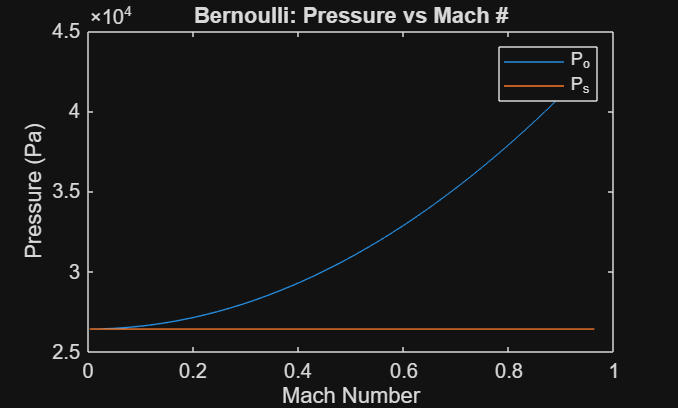

% Bernoulli Relations
h = 10;
[T, P, rho] = stdatm_RosuStefan(h);
P = P*1000; %Pressure in Pa
v = linspace(1,284); % Velocity Vector
q = 0.5*rho*v.^2; % Dynamic Pressure
P_static(1:length(v)) = P;
P_tot = P_static + q;
a = 295; %m/s Speed of sound
Cp = 1005; %J/kg-K
M = v/a;
T_static(1:length(v)) = T;
T_tot = T_static + v.^2/(2*Cp);
rho(1:length(v)) = rho;

figure()
plot(M, P_tot)
hold on
plot(M, P_static)
xlabel('Mach Number');
ylabel('Pressure (Pa)');
title('Bernoulli: Pressure vs Mach #');
legend('P_o', 'P_s')

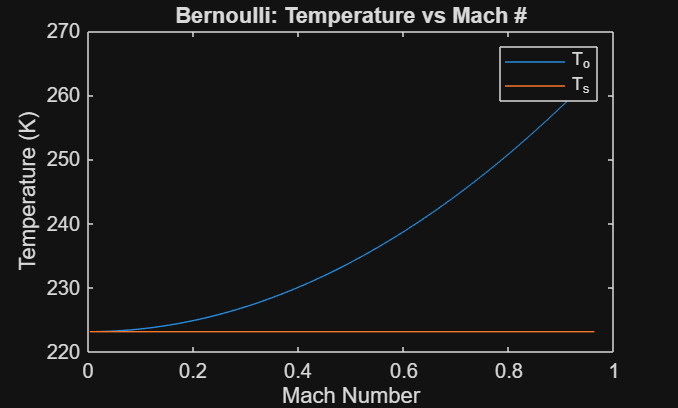

figure()
plot(M, T_tot)
hold on
plot(M, T_static)
xlabel('Mach Number');
ylabel('Temperature (K)');
title('Bernoulli: Temperature vs Mach #');
legend('T_o', 'T_s')

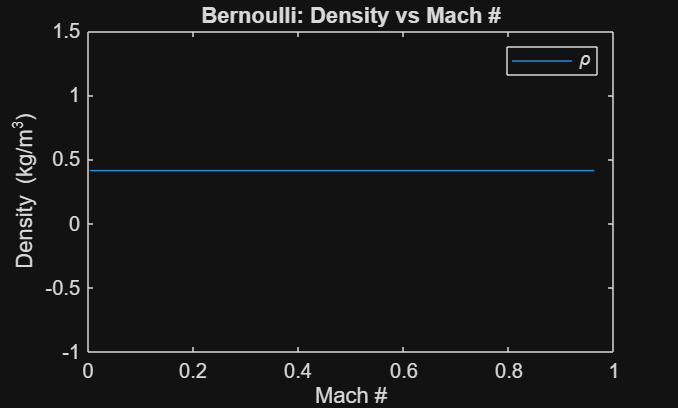

figure()
plot(M, rho)
title('Bernoulli: Density vs Mach #'); 
xlabel('Mach #');
ylabel('Density (kg/m^3)');
legend('\rho') %Makes sense that its a straight line, Bernoulli's assumes constant density

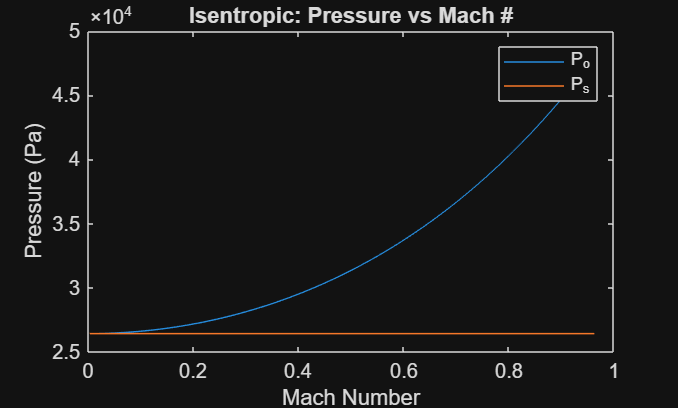

% Isentropic Relations
gamma = 1.4;
P_tot2 = P./(1+(gamma-1)/2.*M.^2).^(-gamma/(gamma-1));
T_tot2 = T.*(1+(gamma-1)/2.*M.^2);
rho_tot2 = rho.*(1+(gamma-1)/2.*M.^2).^(1/(gamma-1));


figure()
plot(M, P_tot2)
hold on
plot(M, P_static)
xlabel('Mach Number');
ylabel('Pressure (Pa)');
title('Isentropic: Pressure vs Mach #');
legend('P_o', 'P_s')

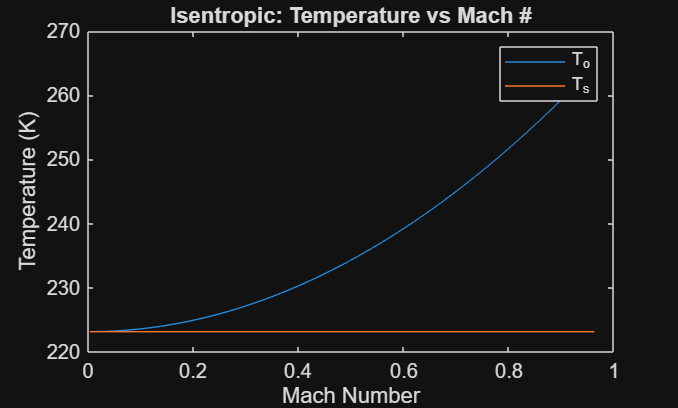

figure()
plot(M, T_tot2)
hold on
plot(M, T_static)
xlabel('Mach Number');
ylabel('Temperature (K)');
title('Isentropic: Temperature vs Mach #');
legend('T_o', 'T_s')

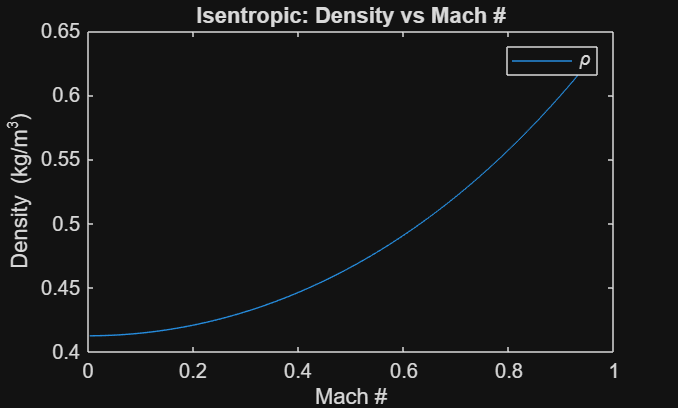

figure()
plot(M, rho_tot2)
title('Isentropic: Density vs Mach #'); 
xlabel('Mach #');
ylabel('Density (kg/m^3)');
legend('\rho')